clear all;
clc;
clf;

## Elevation, Soil, and Visibility data

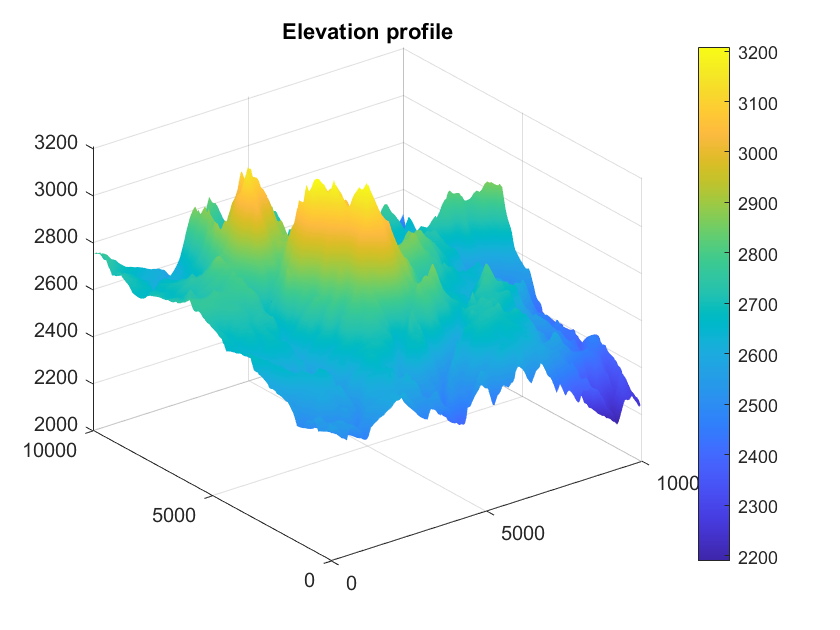

global x_min x_max y_min y_max;

ZM = load('map.txt');
soil = load('soil.txt');
vis = load('visibility.txt');

xv = [0:50:50*(size(ZM,2)-1)];
XM = zeros(size(ZM,2));
for i=1:size(ZM,2)
    XM(i,:) = xv;
end

yv = [0:50:50*(size(ZM,1)-1)]';
YM = zeros(size(ZM,1));
for i=1:size(ZM,1)
    YM(:,i) = yv;
end

clear xv yv;

% Finding min/max for x & y
x_min = min(min(XM));       % This was very computationally expensive if done within the cost function
x_max = max(max(XM));
y_min = min(min(YM));
y_max = max(max(YM));

figure(1);
surf(XM, YM, ZM);
title("Elevation profile");
shading interp;
lims = caxis;
colorbar;

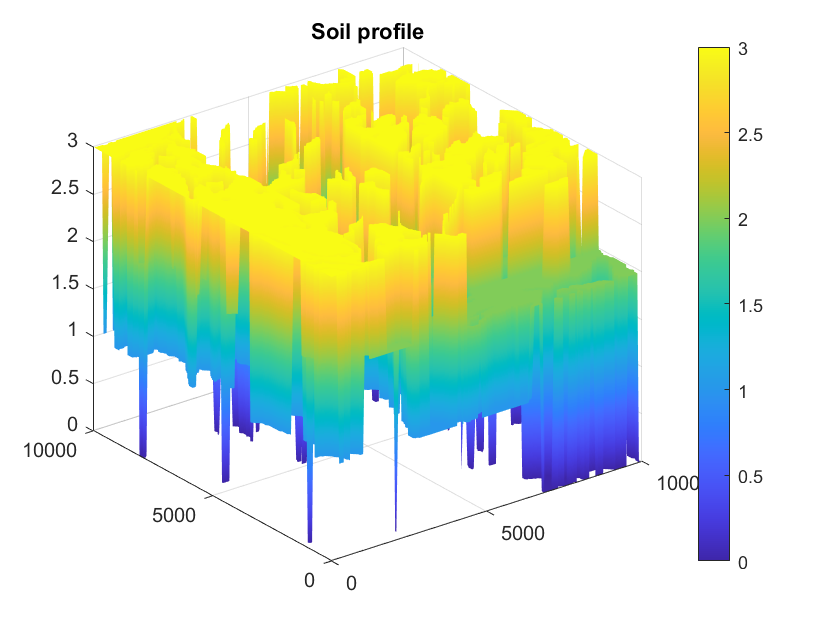

figure(2);
surf(XM,YM,soil);
title("Soil profile");
shading interp;
cmap = colormap;
colorbar;

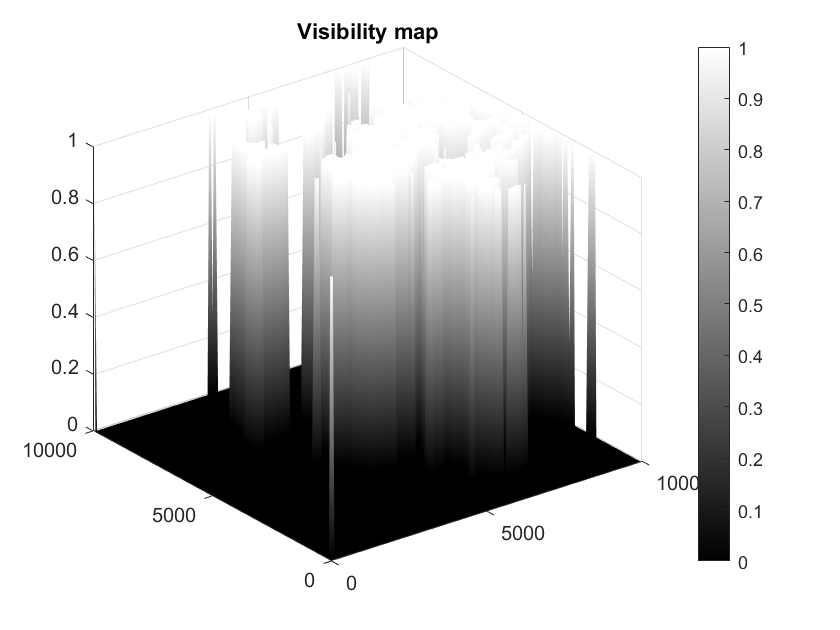

figure(3);
surf(XM,YM,vis);
title("Visibility map");
shading interp;
colormap gray;
colorbar;

## Dynamic Program

% Weights
w1 = 2;     % distance
w2 = 7.5;     % soil
w3 = 10;     % elevation
w4 = 50;     % visibility
max_slope = 0.3;    % 30 percent slope

% Vector storing whether vertex included in shortest path set
incl = zeros(size(YM,1)*size(XM,2), 1);

% Vector storing (*not yet optimal) cost-to-go for each vertex as DP progresses
cost = inf*ones(size(incl));
cost(sub2ind(size(ZM),200,200)) = 0;

tic
% Run Dijkstra till each vertex is included in the shortest path set
while length(incl(incl == 0)) ~= 0
    % Find non-included vertex with min cost-to-go and mark it as included
    cost_temp = cost;
    cost_temp((incl == 1)) = NaN;
    [minV_cost,minV_i] = min(cost_temp);
    incl(minV_i) = 1;

    % Find (x,y) index in Zm for the included vertex
    [r,c] = ind2sub(size(ZM),[minV_i]);

    % Find (x,y) subscript index for adjacent 8 vertices and filter out-of-bound
    % indices
    adj_s = [r-1, c-1;
        r, c-1;
        r+1, c-1;
        r-1, c;
        r+1, c;
        r-1, c+1;
        r, c+1;
        r+1, c+1];
    impos_r = (adj_s(:,1) < 1) | (adj_s(:,1) > 200);
    impos_c = (adj_s(:,2) < 1) | (adj_s(:,2) > 200);
    impos = (impos_r | impos_c);
    adj_s = adj_s((impos ~= 1),:);

    % Find the linear indices for adj_s
    adj_i = sub2ind(size(ZM), adj_s(:,1), adj_s(:,2));

    % Find (x,y,z) coordinates for included vertex
    minV_x = XM(r,c);
    minV_y = YM(r,c);
    minV_z = ZM(r,c);

    % Find (x,y,z) coordinates for adjacent vertices
    adj_x = XM(sub2ind(size(XM),adj_s(:,1), adj_s(:,2)));
    adj_y = YM(sub2ind(size(YM),adj_s(:,1), adj_s(:,2)));
    adj_z = ZM(sub2ind(size(ZM),adj_s(:,1), adj_s(:,2)));

    % Calculate each adjacent vertex's (*not yet optimal) cost-to-go to
    % the vertex included in the beginning of this iteration
    J_dist = sqrt((minV_x - adj_x).^2 + (minV_y - adj_y).^2 + (minV_z - adj_z).^2);
    J_soil = 1./soil(r,c) + 1./soil(sub2ind(size(soil), adj_s(:,1), adj_s(:,2)));
    J_elev = abs(minV_z - adj_z);
    slope = abs(J_elev./sqrt((minV_x - adj_x).^2 + (minV_y - adj_y).^2));
    J_elev(slope >= max_slope) = inf;
    J_vis = vis(r,c)*ones(size(J_elev));
    J = w1*J_dist + w2*J_soil + w3*J_elev + w4*J_vis;

    % Update costs for adjacent vertices if J < cost
    cost(adj_i) = min(cost(adj_i), minV_cost + J);
end

% Optimal cost-to-go at each point
costDP = reshape(cost, [200,200]);

toc

Elapsed time is 6.810484 seconds.


## Visualize Cost Map

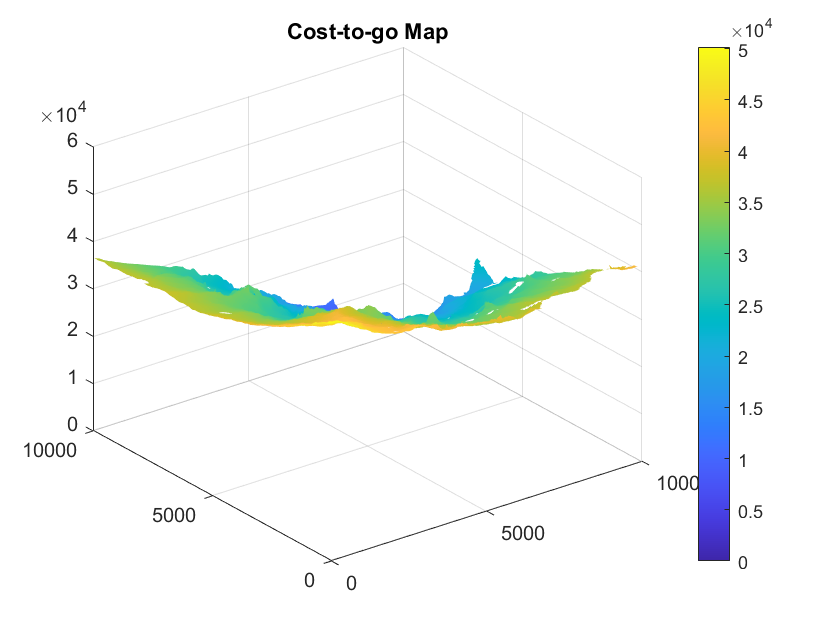

figure(4);
surf(XM, YM, costDP);
title("Cost-to-go Map");
%caxis([0, 5e4]);
shading interp;
colorbar;